addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# Linear Moving Setpoint Controller Optimization Attempt

This script attempts to optimize the response of the linear moving setpoint controller with PID augmented state vector. The script will attempt to get a viable setpoint tracking response that keeps $\beta$ under $25^{\circ}$ and the torque actuation under 73 mNm. 

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 


%Choose a plant model symbolic variable to create a matlab function block from

% plant_model = Lnrzed_EOMs.Lin_EOMs; %Choose the linear decoupled model of the plant.
%plant_model = rhs(BP_Kinetics.NL_NumEOMs); %Choose the coupled nonlinear model as the plant. Torques still approximated

plant_model = Lnrzed_EOMs.Lin_EOMs;

%Replace the definition of the "Plant_Function" MATLAB function block with a
%function generated from obj.plant symbolic function
    sim_path_string = strcat('Repetitive_Controller_1','/Plant/Plant_Function');
    load_system('Repetitive_Controller_1');
    %Generate a matlab function from the linearized plant model
    input_chars = {'x', 'x_dot', 'beta', 'beta_dot','y', 'y_dot', 'gamma', 'gamma_dot', 'T_beta', 'T_gamma' };
    matlabFunctionBlock(sim_path_string, plant_model, 'FunctionName', 'xdot','Vars',input_chars)
            
% 
% if (~exist('LMSPC_PID', 'var'))

    LMSPC_PID = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, plant_model, VDefs, 'SS PID Controller') %In this script, just used to get the matrices of the error dynamics

LMSPC_PID =   Lin_Mvng_Stpt_Cntr_SS with properties:

              VDefs: [1×1 Var_Defs]
           sys_mats: [1×1 struct]
       sim_response: []
          ctrl_type: 'SS PID Controller'
        stateVec_1a: [5×1 sym]
    stateVec_1a_dot: [5×1 sym]
        stateVec_2a: [5×1 sym]
    stateVec_2a_dot: [5×1 sym]
      x_setpointVec: [3×1 sym]
      y_setpointVec: [3×1 sym]
         sim_string: 'Linear_Moving_Setpoint_SS_PID'
              plant: [8×1 sym]



% end

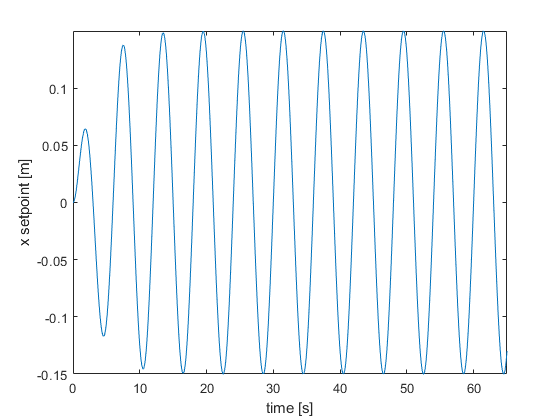

r_sim = .15; % radius of circular trajectory [m]
freq = 1/6; %rotations per second
omega_sim =  2*pi*freq; %angular frequency of circular trajectory 

% %Trajectory symfuns circular
% des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);
% des_traj_sym_y(VDefs.t) = r_sim*sin(omega_sim/2*VDefs.t + pi/2);

%Trajectory symfuns figure 8

des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);
des_traj_sym_y(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);


%Overlay first order smoothing function
T_smooth = 3; %Time constant for first order response

%Trajectory symfuns with first order smoothing overlayed
des_traj_sym_x(VDefs.t) = des_traj_sym_x(VDefs.t)*(1-exp(-VDefs.t/T_smooth));
des_traj_sym_y(VDefs.t) = des_traj_sym_y(VDefs.t)*(1-exp(-VDefs.t/T_smooth));

fplot(des_traj_sym_x) 
xlim([0 65]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

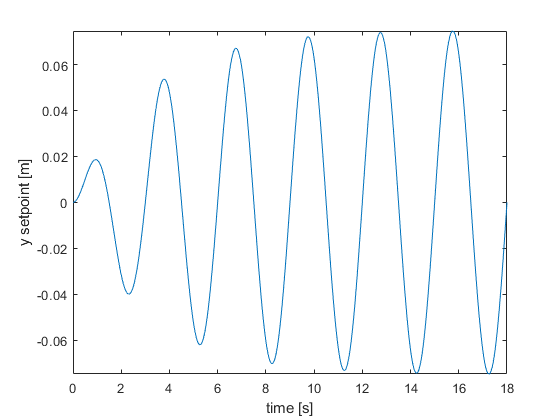


fplot(des_traj_sym_y) 
xlim([0 2*pi/omega_sim*3]); 
ylabel('y setpoint [m]')
xlabel('time [s]')


%Derivative of trajectory
des_traj_sym_dot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t);
des_traj_sym_dot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t);

%Create function handles from the desired trajectory information
des_traj_sym_PID_x = [des_traj_sym_x;des_traj_sym_dot_x];
des_traj_sym_PID_y = [des_traj_sym_y;des_traj_sym_dot_y];

%Set the setpoint functions
%Replace the definition of the "x_Setpoint_Function" MATLAB function block
%with a function generated from x_setpoint_symfun
    sim_path_string = strcat('Repetitive_Controller_1','/x_Setpoint_Function');
    load_system('Repetitive_Controller_1');
    matlabFunctionBlock(sim_path_string, des_traj_sym_PID_x,'FunctionName', 'x_setpoint')

%Replace the definition of the "y_Setpoint_Function" MATLAB function block
%with a function generated from y_setpoint_symfun
    sim_path_string = strcat('Repetitive_Controller_1','/y_Setpoint_Function');
    load_system('Repetitive_Controller_1');
    matlabFunctionBlock(sim_path_string, des_traj_sym_PID_y,'FunctionName', 'y_setpoint')


### K Matrices for the Decoupled Systems


A1a = LMSPC_PID.sys_mats.A1a;
A2a = LMSPC_PID.sys_mats.A2a;

B1a = LMSPC_PID.sys_mats.B1a;
B2a = LMSPC_PID.sys_mats.B2a;

%THESE WORKED WELL ENOUGH FOR r = 0.1, freq = 1/3
% Q_e_ix = 1/15^2; %1/15^2;
% Q_e_x = 1/.001^2*10; %1/.001^2;
% Q_e_xd = 1/.002^2; %1/.002^2; 
% Q_b = 1/deg2rad(40)^2/100 ; %1/deg2rad(40)^2/.5 1/deg2rad(3)^2
% Q_bd = 1/omega_sim^2/1; %1/omega_sim^2/3 1/omega_sim^2

Q_e_ix = 1/15^2;
Q_e_x = 1/.001^2;
Q_e_xd = 1/.002^2; 
Q_b = 1/deg2rad(40)^2/.5; 
Q_bd = 1/omega_sim^2/3;

% Q_e_ix = 1000; %
% Q_e_x = 1/.001^2*10; %
% Q_e_xd = 1/.002^2; %
% Q_b = 25000000000 ; %
% Q_bd = 2; %

Q = [Q_e_ix 0 0 0 0; 
     0 Q_e_x 0 0 0;
     0 0 Q_e_xd 0 0;
     0 0 0 Q_b 0;
     0 0 0 0 Q_bd];

R = 1/(73/1000)^2/2; 

K_PID1 = lqr(double(A1a), double(B1a), Q,R)

K_PID1 =    -0.0069 -105.4716  -79.4599  127.2998   16.4731


K_PID1([4,5]) = -K_PID1([4,5])

K_PID1 =    -0.0069 -105.4716  -79.4599 -127.2998  -16.4731



K_PID2 = lqr(double(A2a), double(B2a), Q,R)

K_PID2 =     0.0069  105.4716   79.4599  127.2998   16.4731


K_PID2([4,5]) = -K_PID2([4,5])

K_PID2 =     0.0069  105.4716   79.4599 -127.2998  -16.4731


### Simulate Responses

%Specify simulation time
% tspan = [0 15*pi/omega_sim];
tspan = [0 5];

x_0 = [0; 0; 0; 0; 0; 0; 0; 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

T_x = 1/freq; %Setpoint's period
T_y = T_x;
Tstart_x = 3*T_x;
Tstart_y = T_y;

Tau_filt = 0.0;
Tmax = VDefs.Tmax*1000; %Torque saturation

simout = sim('Repetitive_Controller_1')

simout =   Simulink.SimulationOutput:

                   tout: [590x1 double] 
                      u: [590x2 double] 
                      x: [590x8 double] 
                x_s_vec: [590x4 double] 
                y_s_vec: [590x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


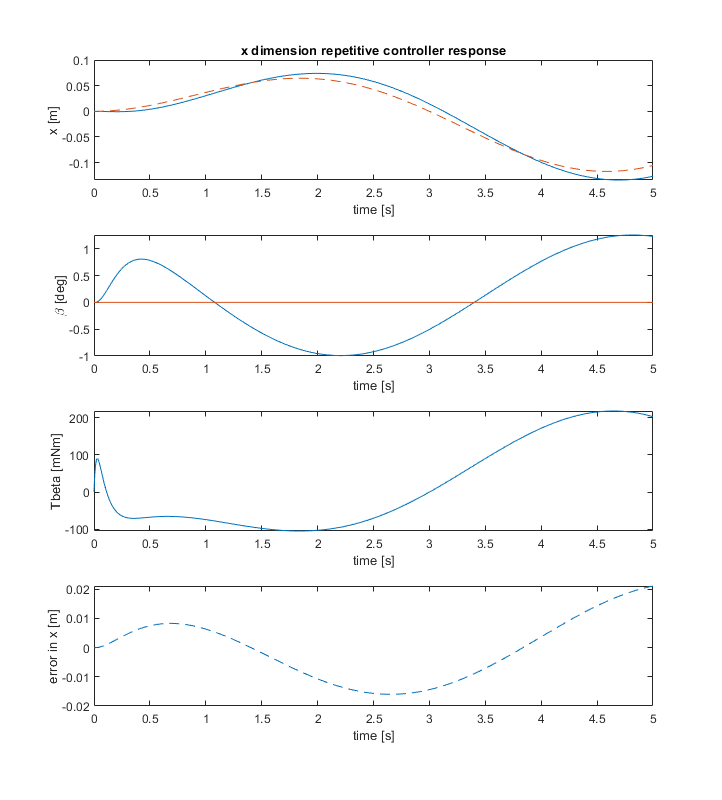

% plot(simout.tout, simout.x(:,1),simout.tout, simout.x_s_vec(:,1)), 
% xlabel('time [s]')
% ylabel('position [m]')
% legend('x', 'x_s')

ax1 = subplot(4,1,1);
plot(simout.tout,simout.x(:,1),...
     simout.tout,simout.x_s_vec(:,1),'--' )
xlabel('time [s]')
ylabel('x [m]')
title('x dimension repetitive controller response')



ax2 = subplot(4,1,2);
plot(simout.tout,rad2deg(simout.x(:,3)),simout.tout, rad2deg(simout.x_s_vec(:,3)))
xlabel('time [s]')
ylabel('\beta [deg]')


ax3 = subplot(4,1,3);
plot(simout.tout,simout.u(:,1)*1000)
xlabel('time [s]')
ylabel('Tbeta [mNm]')

ax4 = subplot(4,1,4);
plot(simout.tout,(simout.x_s_vec(:,1) - simout.x(:,1)),'--' )
xlabel('time [s]')
ylabel('error in x [m]')

linkaxes([ax1,ax2, ax3, ax4],'x');
set(gcf,'position',[0,0,800,900]);   



% figure
% plot(simout.tout, simout.x(:,3), simout.tout, simout.x_s_vec(:,3))